## n pixel hex vs rec

clear;
clf;
feature('SetPrecision', 24);
plotmargin =  0.5;                    % margin in pixel width
drawplot = false;                   % plot result
equalres = false;                   % penalty for hex, to get same pixels / A
N=100;                              % Samples in X to simulate
d=.06;                              % Distance between LEDs
%H =[.05:0.01:0.07];                % siulate over h
dtoh = .7:.05:1.6;                   %   or d over h
I_0 = 1;                             % Luminous Intensity
n=[10 12];                          % number of LEDs

% to make this more efficient: calculate data once, unse symmetry, shift and
% % add for every led p


if (dtoh ~= 0)
    H = dtoh.^-1*d;
end

if equalres
    arec = d^2;
    ahex = d^2/2*sqrt(3);
    % sqrt(A/(2*sqrt(3)))*2
    dhex = 2*sqrt(2*d^2/3/sqrt(3));
else
    dhex = d;
end

% Vector of indices X
X(2,n(1)*n(2)) = 0;
idx = 0;
for i=1:n(2) %iterate over y
    for j=1:n(1) %iterate over x
        idx = idx + 1;
        X(1,idx) = mod(idx-1,n(1))+1;
        X(2,idx) = i;
    end
end
clear idx;
clear i j;

% rectangular positions
Xr_pos= X*d;

% hexagonal positions
Xh_pos(2,length(X(1,:))) = 0;
for i=1:length(X(1,:))
    Xh_pos(:,i) = getHexPos(X(:,i),dhex);
end

% todo : Kontrastmessung für kleinste Zelle
if(0) % hex 7 cell dirty switch here... delete idx 9 and 7 to get symmetric cell
    Xh_pos(:,9) = [];
    Xh_pos(:,7) = [];
end
if(0) % turn ctr led off
    Xh_pos(:,5) = [];
    Xr_pos(:,5) = [];
end

% margin to plotwindow

xr_min = min(Xr_pos(1,:)) -d*plotmargin;
xr_max = max(Xr_pos(1,:)) +d*plotmargin;
yr_min = min(Xr_pos(2,:)) -d*plotmargin;
yr_max = max(Xr_pos(2,:)) +d*plotmargin;


xh_min = min(Xh_pos(1,:)) -0.75*dhex*plotmargin;
xh_max = max(Xh_pos(1,:)) +0.75*dhex*plotmargin;
yh_min = min(Xh_pos(2,:)) -0.75*dhex*plotmargin;
yh_max = max(Xh_pos(2,:)) +0.75*dhex*plotmargin;


xr = linspace(xr_min,xr_max,N);
yr = linspace(yr_min,yr_max,round(N*yr_max/xr_max));
[xr,yr] = meshgrid(xr,yr);

xh = linspace(xh_min,xh_max,N);

yh = linspace(yh_min,yh_max,round(N*yh_max/xh_max));
[xh,yh] = meshgrid(xh,yh);

% allocate
K_mh(length(H)) = 0;
K_mr(length(H)) = 0;
E_0h(length(H)) = 0;
clear E_large_rec E_large_hex;
E_large_rec(length(xr(:,1)),length(yr(1,:)),length(H)) = 0;
E_large_hex(length(xh(:,1)),length(yh(1,:)),length(H)) = 0;

% Simulate Illuminance. Inefficient approach... better: calculate E for one point and
% shift Matrix

z = 0; %iteration counter
for h=H %iterate over height
    z = z + 1; %iterator
    
    % E over a single LED
    E_0h(z) = I_0 / h^2;
    
    % Rectangular Matrix
    for i=1:length(Xr_pos(1,:))
        E_large_rec(:,:,z) = E_large_rec(:,:,z) + GenerateE(xr,yr,Xr_pos(1,i),Xr_pos(2,i),h,I_0);

    end
    clear i;
    
    % Hexagonal Matrix
    for i=1:length(Xh_pos(1,:))
        E_large_hex(:,:,z) = E_large_hex(:,:,z) + GenerateE(xh,yh,Xh_pos(1,i),Xh_pos(2,i),h,I_0);
    end
    clear i;
    
end

## Plot and Statistics

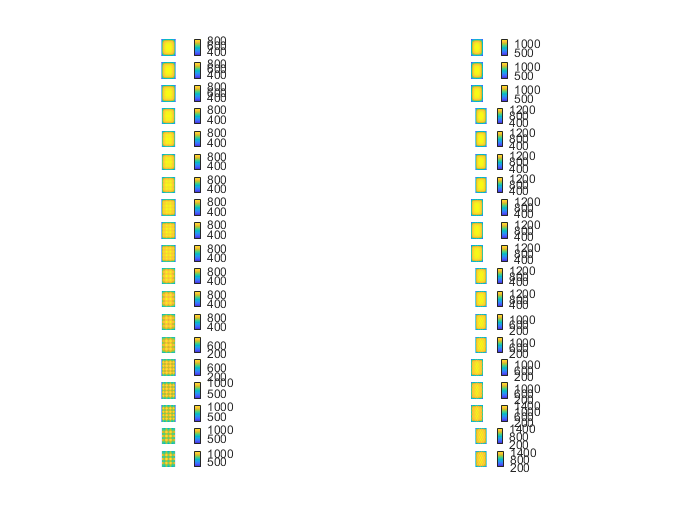

figureAllplots = figure();
plotEqualCaxis = 0; % 2 - one colorbar for all, 2 - one colorbar per height, 0 - one colorbar per plot
plotBoth = true;
%colormap(parula(32))
% Maximum and minimum Illuminance
clear E_hamx E_rmax;
E_hmax(length(H)) = 0;
E_rmax(length(H)) = 0;
E_hmin(length(H)) = 0;
E_rmin(length(H)) = 0;
for i=1:length(H)
    E_hmax(i) = max(max(E_large_hex(:,:,i)));
    E_rmax(i) = max(max(E_large_rec(:,:,i)));
    E_hmin(i) = min(min(E_large_hex(:,:,i)));
    E_rmin(i) = min(min(E_large_rec(:,:,i)));
end
E_max = max(max(E_hmax),max(E_rmax));
E_min = min(min(E_hmin),min(E_rmin));



z = 0; %iteration counter
if drawplot
    
end
for h=H %iterate over height
    z = z + 1; %iterator
    
    %plot rec
    if plotBoth
        subplot(length(H),2,2*z-1);
    end
    caxis([0 E_max]);
    imagesc(xr(1,:),yr(:,1),E_large_rec(:,:,z));
    axis image;
    axis off;
    ax = gca;
    if (plotEqualCaxis == 1)
        ax.CLim = [E_min E_max];
    elseif (plotEqualCaxis == 2)
        ax.CLim = [min(E_hmin(z),E_rmin(z)) max(E_hmax(z),E_rmax(z))];
    end
    colorbar;
    descr = ['E in lux, $ d=',num2str(d*100),'cm, h=',num2str(h*100),'cm $'];
 %   title(descr,'Interpreter','latex');
    
    %xlabel(descr,'Interpreter','latex');
    clear ax;
    
    %plot hex
    if plotBoth
        
        subplot(length(H),2,2*z);
        imagesc(xh(1,:),yh(:,1),E_large_hex(:,:,z)); %skalierte farben
        axis image;
        axis off;
        %    colorbar('Ticks',[E_min,E_max])
        ax = gca;
        if (plotEqualCaxis == 1)
            ax.CLim = [E_min E_max];
        elseif (plotEqualCaxis == 2)
            ax.CLim = [min(E_hmin(z),E_rmin(z)) max(E_hmax(z),E_rmax(z))];
        end
        colorbar;
        descr = ['E in lux, $ d=',num2str(d*100),'cm, h=',num2str(h*100),'cm $'];
    %    title(descr,'Interpreter','latex');
        clear ax;
        
    end    
end

## Evaluete Data

window = 0.75;
r=window/2;

Nx = length(E_large_hex(:,1,1))

Nx = 142

Ny = length(E_large_hex(1,:,1))

Ny = 100

E_small_hex = E_large_hex(round(Nx/2-Nx*r:Nx/2+Nx*r),round(Ny/2-Ny*r:Ny/2+Ny*r),:);
Nx = length(E_large_rec(:,1,1))

Nx = 119

Ny = length(E_large_rec(1,:,1))

Ny = 100

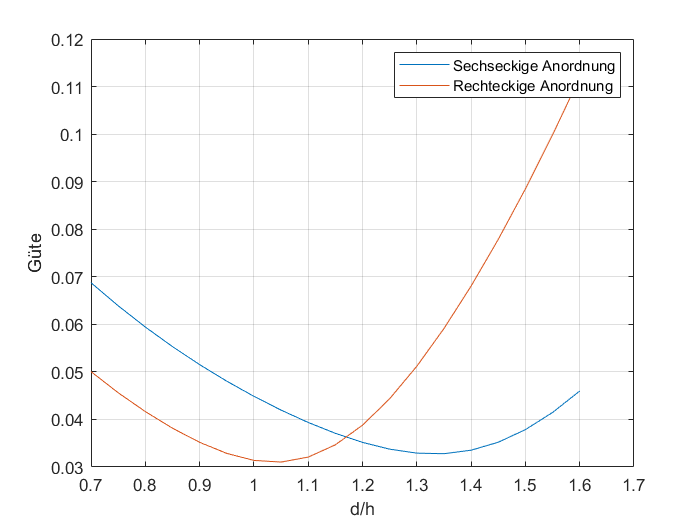

E_small_rec = E_large_rec(round(Nx/2-Nx*r:Nx/2+Nx*r),round(Ny/2-Ny*r:Ny/2+Ny*r),:);

% E_small_hex = E_large_hex;
% E_small_rec = E_large_rec;

E_small_hex_mean = mean(mean(E_small_hex));
E_small_rec_mean = mean(mean(E_small_rec));

rmse_hex = reshape(sqrt(mean(mean((E_small_hex-E_small_hex_mean).^2)))./E_small_hex_mean,[1 length(H)]);
rmse_rec = reshape(sqrt(mean(mean((E_small_rec-E_small_rec_mean).^2)))./E_small_rec_mean,[1 length(H)]);

E_small_hex_mean = reshape(E_small_hex_mean,[1 length(H)]);
E_small_rec_mean = reshape(E_small_rec_mean,[1 length(H)]);


figure1 = figure();
plot(d./H,rmse_hex,'DisplayName','Sechseckige Anordnung');
hold on;
plot(d./H,rmse_rec,'DisplayName','Rechteckige Anordnung');% Create axes
ylabel('Güte');
xlabel('d/h');

% title({'Root Mean Square Error'});

box('on');
legend('show');
grid on;

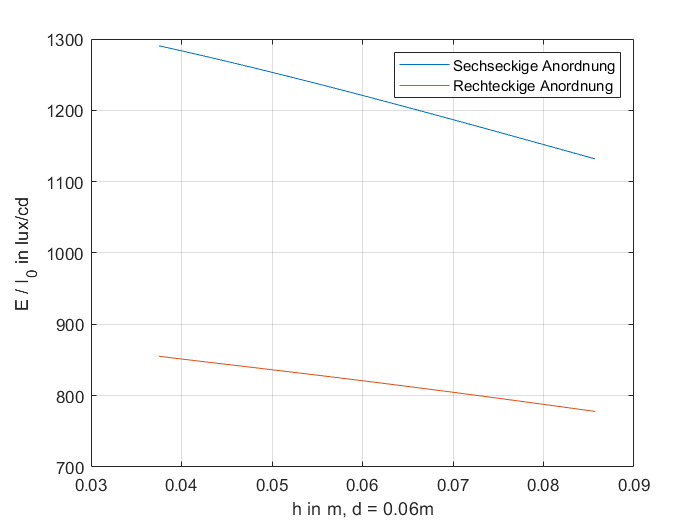


figure2 = figure();
plot(H,E_small_hex_mean,'DisplayName','Sechseckige Anordnung');
hold on;
plot(H,E_small_rec_mean,'DisplayName','Rechteckige Anordnung');% Create axes
ylabel('E / I_0 in lux/cd');
xlabel('h in m, d = '+string(d)+'m');

% title({'Root Mean Square Error'});

box('on');
legend('show');
grid on;

## Kontrast

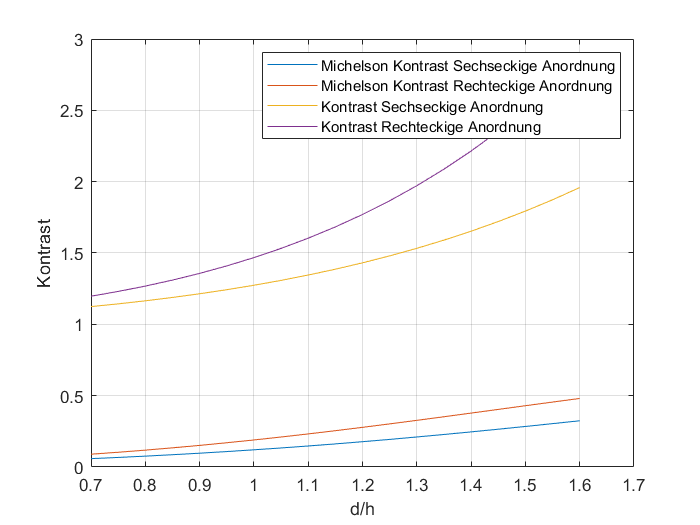

k_h = E_hmax./(E_hmax-E_0h);
k_r = E_rmax./(E_rmax-E_0h);

% Michelson Kontrast

k_mh = (E_hmax-(E_hmax-E_0h)) ./ (E_hmax+(E_hmax-E_0h));
k_mr = (E_rmax-(E_rmax-E_0h)) ./ (E_rmax+(E_rmax-E_0h));

figure3 = figure();
plot(d./H,k_mh,'DisplayName','Michelson Kontrast Sechseckige Anordnung');
hold on;
plot(d./H,k_mr,'DisplayName','Michelson Kontrast Rechteckige Anordnung');
plot(d./H,k_h,'DisplayName','Kontrast Sechseckige Anordnung');
plot(d./H,k_r,'DisplayName','Kontrast Rechteckige Anordnung');
ylabel('Kontrast');
xlabel('d/h');

% title({'Root Mean Square Error'});

box('on');
legend('show');
grid on;

## Tabelle


T = table(dtoh',k_mh',k_mr',rmse_hex',rmse_rec',E_hmax',E_rmax',E_small_hex_mean',E_small_rec_mean');

T.Properties.VariableNames = {'dtoh' 'k_mh' 'k_mr' 'rmse_hex' 'rmse_rec' 'E_hmax' 'E_rmax' 'E_small_hex_mean' 'E_small_rec_mean'};
T

T = 19×9 table
    dtoh      k_mh        k_mr      rmse_hex    rmse_rec    E_hmax    E_rmax    E_small_hex_mean    E_small_rec_mean
    ____    ________    ________    ________    ________    ______    ______    ________________    ________________

     0.7    0.058473    0.089689    0.068748    0.050057    1231.9    826.85         1131.9              777.89     
    0.75    0.066947     0.10336     0.06391    0.045618    1245.1    834.01           1152              787.84     
     0.8    0.076146     0.11821    0.059439    0.041655    1256.2    840.85         1169.5              796.39     
    0.85    0.086075     0.13426    0.055319    0.038164    1266.2    847.74         1184.9  

fid=fopen('tabelle.txt','wt'); 
Tab = [dtoh'   k_mh' k_mr' rmse_hex' rmse_rec' E_hmax',E_rmax' E_small_hex_mean' E_small_rec_mean'];
fs = '%.2f  &   %.3f    &   %.3f    &   %.4f    &   %.4f    &   %.2f    &   %.2f    &   %.2f    &   %.2f \\\\\n';
fprintf(fid,fs,Tab');
fclose(fid);